% Main File to generate Baseline Model Figures 10-11
close all; clear; clc

load ICs_baseline
load baseline_parameter_inputs

% ========================================================================
%  START: EXPERIMENTAL CONFIGURATION BLOCK
% ========================================================================

% --- 1. SELECT WHICH MODEL TO RUN ---
% 0 = Baseline (Isogenic Control)
% 1 = Model 1 (IKr Defect Only)
% 2 = Model 2 (IKr + INa,L)
% 3 = Model 3 (IKr + ICa,P)
% 4 = Model 4 (All Three Defects)
model_to_run = 0; % <--- CHANGE THIS NUMBER TO SELECT YOUR EXPERIMENT

% --- 2. Define Parameter Indices ---
g_Kr_index = 7;   % Conductance of IKr
g_Na_index = 40;  % Conductance of INa (proxy for late current)
p_CaL_index = 30; % Permeability of ICaL (for persistent current)

% --- 3. Apply Modifications Based on Selection ---
modified_params = baseline_parameter_inputs; % Start with the baseline

if model_to_run == 1
    plot_title = 'Model 1: IKr Defect Only';
    % Apply 72.5% IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    
elseif model_to_run == 2
    plot_title = 'Model 2: IKr + INa,L';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    % Apply 2.31-fold INa,L increase
    modified_params(g_Na_index) = modified_params(g_Na_index) * 2.31;
    
elseif model_to_run == 3
    plot_title = 'Model 3: IKr + ICa,P';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    % Apply 2.29-fold ICa,P increase
    modified_params(p_CaL_index) = modified_params(p_CaL_index) * 2.29;
    
elseif model_to_run == 4
    plot_title = 'Model 4: All Three Defects';
    % Apply all three modifications
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    modified_params(g_Na_index) = modified_params(g_Na_index) * 2.31;
    modified_params(p_CaL_index) = modified_params(p_CaL_index) * 2.29;
    
else % Default to baseline if model_to_run is 0 or any other number
    plot_title = 'Baseline Model (Isogenic Control)';
end

% Overwrite the original variable with our modified one for the simulation
baseline_parameter_inputs = modified_params;
% ========================================================================
%  END: CONFIGURATION BLOCK
% ========================================================================

## Run iPSC_function

options = odeset('MaxStep',1,'InitialStep',2e-2);
run_time=3e3;
[Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, baseline_parameter_inputs);
Cai=values(:,3);
Vm=values(:,1);

## Calculate select current traces:

INaCa = zeros(size(Time));
IpCa = zeros(size(Time));
Iup = zeros(size(Time));
for i= 1:size(values,1)
    [~, update_step_i] =  ipsc_function(Time(i), values(i,:),  baseline_parameter_inputs);
    INaCa(i) = update_step_i(8);
    IpCa(i) = update_step_i(9);
    Iup(i) = update_step_i(14);
end

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

%ca_analysis( Time, Iup, INaCa, IpCa, Cai, plot_title )

## Figure 11A: action potential trace for baseline model

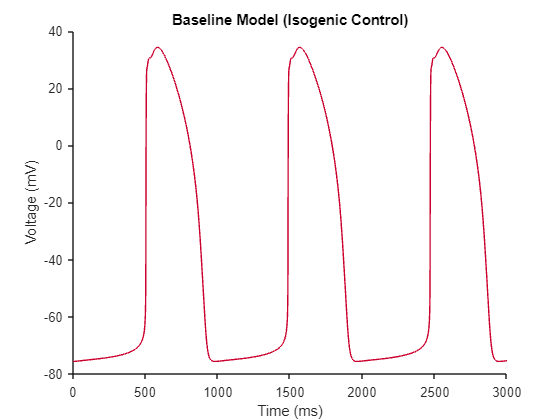

figure,set(gcf,'color','w')
plot(Time, Vm,'Color', [.8 0 .18]);
set(gca,'box','off','tickdir','out')
ylabel('Voltage (mV)');
xlabel('Time (ms)')
title(plot_title)

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

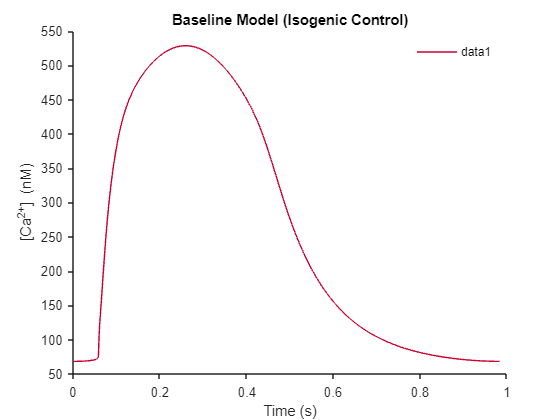

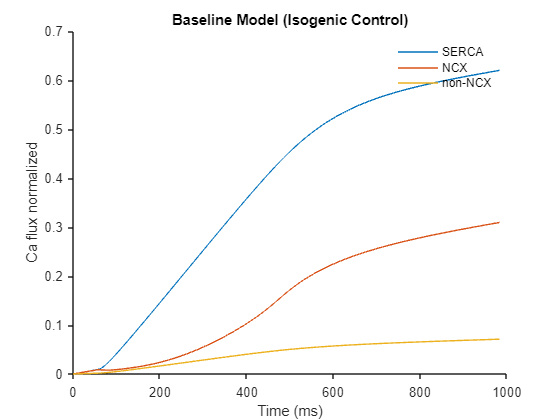

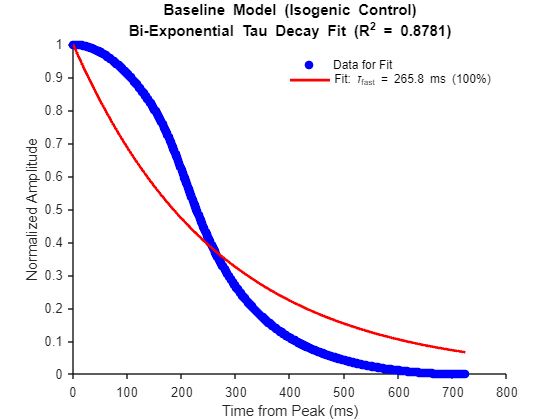

ca_results = ca_analysis( Time, Iup, INaCa, IpCa, Cai, plot_title );

## ========================================================================

fprintf('\n\n--- DATA TABLES FOR: %s ---\n', plot_title);



--- DATA TABLES FOR: Baseline Model (Isogenic Control) ---



% --- Display Calcium and Flux Tables (from ca_analysis) ---
fprintf('\n## Table 1: Calcium Transient Morphology ##\n');


## Table 1: Calcium Transient Morphology ##


fprintf('%-30s | %-10.2f\n', 'Peak [Ca²⁺] (nM)', ca_results.peak_ca_nM);

Peak [Ca²⁺] (nM)               | 528.55    


fprintf('%-30s | %-10.2f\n', 'Diastolic [Ca²⁺] (nM)', ca_results.diastolic_ca_nM);

Diastolic [Ca²⁺] (nM)          | 68.42     


fprintf('%-30s | %-10.2f\n', 'Time to Peak (ms)', ca_results.ttp_ms);

Time to Peak (ms)              | 200.47    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Fast (ms)', ca_results.tau_fast_ms);

Tau Decay Fast (ms)            | 265.84    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Slow (ms)', ca_results.tau_slow_ms);

Tau Decay Slow (ms)            | 478.19    


fprintf('%-30s | %-10.2f\n', 'R^2 Tau Decay', ca_results.tau_decay_r_squared);

R^2 Tau Decay                  | 0.88      



fprintf('\n## Table 2: %% Contribution of Calcium Flux ##\n');


## Table 2: % Contribution of Calcium Flux ##


fprintf('%-30s | %-10.1f%%\n', 'SERCA', ca_results.pct_serca);

SERCA                          | 62.0      %


fprintf('%-30s | %-10.1f%%\n', 'NCX', ca_results.pct_ncx);

NCX                            | 30.9      %


fprintf('%-30s | %-10.1f%%\n', 'Non-NCX (I_pCa)', ca_results.pct_ipca);

Non-NCX (I_pCa)                | 7.1       %


## Calculate and Display AP Morphology Table


% --- Calculate and Display AP Morphology Table ---
% Isolate a single, stable beat for AP analysis
time_start = 800; time_end = 1600;
beat_indices = find(Time >= time_start & Time < time_end);
Time_beat = Time(beat_indices);
Vm_beat = Vm(beat_indices);

% MDP, Peak AP, and Amplitude
mdp = min(Vm_beat);
peak_ap = max(Vm_beat);
ap_amplitude = peak_ap - mdp;

% Max Upstroke Velocity (dVm/dt)
dVm_dt = diff(Vm_beat) ./ diff(Time_beat);
max_upstroke_velocity = max(dVm_dt);
[~, upstroke_idx_local] = max(dVm_dt);
time_of_upstroke = Time_beat(upstroke_idx_local);

% APD50 and APD90 Calculation
repol_50_level = peak_ap - 0.50 * ap_amplitude;
repol_90_level = peak_ap - 0.90 * ap_amplitude;
peak_ap_idx_local = find(Vm_beat == peak_ap, 1);
repol_Vm = Vm_beat(peak_ap_idx_local:end);
repol_Time = Time_beat(peak_ap_idx_local:end);

time_apd50 = interp1(repol_Vm, repol_Time, repol_50_level);
time_apd90 = interp1(repol_Vm, repol_Time, repol_90_level);

apd50 = time_apd50 - time_of_upstroke;
apd90 = time_apd90 - time_of_upstroke;

fprintf('\n## Table 3: Action Potential Morphology ##\n');


## Table 3: Action Potential Morphology ##


fprintf('%-30s | %-10.2f\n', 'APD90 (ms)', apd90);

APD90 (ms)                     | NaN       


fprintf('%-30s | %-10.2f\n', 'APD50 (ms)', apd50);

APD50 (ms)                     | NaN       


fprintf('%-30s | %-10.2f\n', 'Amplitude (mV)', ap_amplitude);

Amplitude (mV)                 | 109.87    


fprintf('%-30s | %-10.2f\n', 'Upstroke Velocity (V/s)', max_upstroke_velocity);

Upstroke Velocity (V/s)        | 33.30     


fprintf('%-30s | %-10.2f\n', 'Maximum Diastolic Potential (mV)', mdp);

Maximum Diastolic Potential (mV) | -75.60    


fprintf('\n');